size_list=45

size_list = 45

c_gains=logspace(-4,3,size_list)

c_gains = 	1.0e+03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0007    0.0009    0.0014    0.0020    0.0028    0.0041    0.0059    0.0085    0.0123    0.0178    0.0257    0.0370    0.0534    0.0770    0.1110    0.1602    0.2310    0.3332    0.4806    0.6933    1.0000


m_e=0.1;
k_e=50;
Ptbe_list=logspace(-4,3,size_list)

Ptbe_list = 	1.0e+03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0007    0.0009    0.0014    0.0020    0.0028    0.0041    0.0059    0.0085    0.0123    0.0178    0.0257    0.0370    0.0534    0.0770    0.1110    0.1602    0.2310    0.3332    0.4806    0.6933    1.0000


plot_k_e_max=[]


plot_k_e_max =

     []



for i=1:length(c_gains)
    for j=1:length(Ptbe_list)
        P_t=c_gains(i);
        I_m=c_gains(j);
        b_e=Ptbe_list(i)/P_t;
        passivityCheck;
        if passivity==1
        plot_k_e_max=[plot_k_e_max; c_gains(i) Ptbe_list(j) K*(c_gains(i)*(1+Ptbe_list(j)))/(c_gains(i)+K) eval(m_e_max) eval(k_e_max) b_e];
        end
        
        end
end
dotsize=25

dotsize = 25

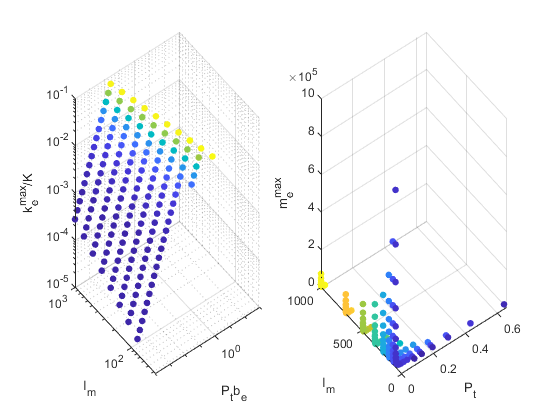

figure
subplot1 =subplot(1,2,1);
scatter3(plot_k_e_max(:,1), plot_k_e_max(:,2), plot_k_e_max(:,3)/K, dotsize, plot_k_e_max(:,3), 'filled')

zlabel('k_{e}^{max}/K','FontSize',20);
ylabel('I_{m}','FontSize',20);
xlabel('P_{t}b_e','FontSize',20);
xlim(subplot1,[0 1000]);
ylim(subplot1,[0 1000]);
view(subplot1,[-37.5 30]);
grid(subplot1,'on');
set(subplot1,'XMinorTick','on','XScale','log','YMinorTick','on','YScale',...
    'log','ZMinorTick','on','ZScale','log');
axes1 = axes('Position',[0.515591568721513 0.11 0.334659090909091 0.815]);
hold(axes1,'on');
subplot2 =subplot(1,2,2);
scatter3(plot_k_e_max(:,1), plot_k_e_max(:,2), plot_k_e_max(:,4), dotsize, plot_k_e_max(:,5), 'filled')
zlabel('m_{e}^{max}','FontSize',20);
ylabel('I_{m}','FontSize',20);
xlabel('P_{t}','FontSize',20);

xlim(axes1,[0 1000]);

Error using xlim (line 31)
Invalid or deleted graphics object.

ylim(axes1,[0 1000]);
view(axes1,[-37.5 30]);
grid(axes1,'on');
set(axes1,'XMinorTick','on','XScale','log','YMinorTick','on','YScale','log',...
    'ZMinorTick','on','ZScale','log');
colorbar(axes1,'Position',...
    [0.858931398416885 0.113490401396161 0.03 0.812784090909091]);

% colorbar
% ylabel(colorbar, 'k_{e}^{max}')
% size_list=10
% c_gains=logspace(-2,3,size_list)
% tau_list=logspace(-4,0,size_list)
% m_e_list=logspace(-3,1,size_list)
% b_e_list=logspace(-3,1,size_list)
% k_e_list=logspace(-3,1,size_list)
% plot_list=[]
% for i=1:length(c_gains)
%     for j=1:length(c_gains)
%         for k=1:length(b_e_list)
%                 P_t=c_gains(i);
%                 I_m=c_gains(j);
%                 b_e=b_e_list(k);
%                 passivityCheck;
%                 if passivity==1
%                     plot_list=[plot_list;P_t I_m b_e eval(k_e_max)];
%                 end
% %         plot_k_e(i,j)=eval(k_e_max);
% %         plot_m_e(i,j)=eval(m_e_max);
% %         plot_routh(i,j)=eval(eps1);
% %         plot_d_4(i,j)=eval(d_4);
% %         plot_d_6(i,j)=eval(d_6);
% %         plot_d_8(i,j)=eval(d_8);
%         end
%        
%     end
% end
% [X,Y] = meshgrid(plot_list(:,1),plot_list(:,2));
% Z=meshgrid(plot_list(:,3));
% C=meshgrid(plot_list(:,4));
% scatter3(plot_list(:,1),plot_list(:,2),plot_list(:,3),[25],plot_list(:,4))
% set(gca, 'YScale', 'log')
% set(gca, 'XScale', 'log')
% set(gca, 'ZScale', 'log')
% xlabel('P_{t}') 
% ylabel('I_{m}')
% zlabel('b_{e}')
% colorbar; ylabel(colorbar, 'k_{e}^{max}')
% Z=meshgrid(plot_list(:,5));
% C=meshgrid(plot_list(:,3));
% surf3(X,Y,Z,C)
% set(gca, 'YScale', 'log')
% set(gca, 'XScale', 'log')
% set(gca, 'ZScale', 'log')
% set(gca,'ColorScale','log')
% xlabel('P_{t}') 
% ylabel('I_{m}')
% zlabel('b_{e}')